clc;clear;close all;

## 单次绘制

plot_pareto(result.fval)
plot_pareto_smooth(result.fval)

## 读取

fval_all = [];
for i = 1:21
    msg = sprintf('F:\\Archive 归档\\0522_mp\\data\\result_run_%d.mat',i);
    load(msg);
    fval_all = [fval_all; result.fval];
end
plot_pareto(fval_all)


## 2d paretoFront

idx = fval_all(:,3) == 11;
data_11 = fval_all(idx,:);
pareto(data_11(:,2),data_11(:,1))
XY = data_11(:,1:2);
n = size(XY,1);
isPF = true(n,1);

for i = 1:n
    for j = 1:n
        if all(XY(j,:) <= XY(i,:)) && any(XY(j,:) < XY(i,:))
            isPF(i) = false;
            break;
        end
    end
end

PF = XY(isPF,:);
figure;
scatter(XY(:,1),XY(:,2),30,'b','filled');
hold on;
scatter(PF(:,1),PF(:,2),80,'r','filled');
xlabel('x');
ylabel('y');
legend('All points','Pareto front');
grid on


## 3d pareto合并

初始Pareto点数量: 49
拒绝加入 [  1/ 51]
拒绝加入 [  2/ 51]
拒绝加入 [  3/ 51]
加入成功 [  4/ 51]   当前数量: 50
加入成功 [  5/ 51]   当前数量: 51
加入成功 [  6/ 51]   当前数量: 52
拒绝加入 [  7/ 51]
拒绝加入 [  8/ 51]
加入成功 [  9/ 51]   当前数量: 53
拒绝加入 [ 10/ 51]
拒绝加入 [ 11/ 51]
拒绝加入 [ 12/ 51]
拒绝加入 [ 13/ 51]
拒绝加入 [ 14/ 51]
加入成功 [ 15/ 51]   当前数量: 54
拒绝加入 [ 16/ 51]
拒绝加入 [ 17/ 51]
拒绝加入 [ 18/ 51]
拒绝加入 [ 19/ 51]
拒绝加入 [ 20/ 51]
拒绝加入 [ 21/ 51]
拒绝加入 [ 22/ 51]
拒绝加入 [ 23/ 51]
拒绝加入 [ 24/ 51]
拒绝加入 [ 25/ 51]
加入成功 [ 26/ 51]   当前数量: 55
拒绝加入 [ 27/ 51]
拒绝加入 [ 28/ 51]
拒绝加入 [ 29/ 51]
拒绝加入 [ 30/ 51]
拒绝加入 [ 31/ 51]
拒绝加入 [ 32/ 51]
拒绝加入 [ 33/ 51]
拒绝加入 [ 34/ 51]
拒绝加入 [ 35/ 51]
拒绝加入 [ 36/ 51]
拒绝加入 [ 37/ 51]
加入成功 [ 38/ 51]   当前数量: 56
拒绝加入 [ 39/ 51]
拒绝加入 [ 40/ 51]
加入成功 [ 41/ 51]   当前数量: 57
拒绝加入 [ 42/ 51]
拒绝加入 [ 43/ 51]
拒绝加入 [ 44/ 51]
拒绝加入 [ 45/ 51]
拒绝加入 [ 46/ 51]
拒绝加入 [ 47/ 51]
拒绝加入 [ 48/ 51]
加入成功 [ 49/ 51]   当前数量: 58
拒绝加入 [ 50/ 51]
拒绝加入 [ 51/ 51]

最终Pareto点数量: 58


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 58
拒绝加入 [  1/ 55]
拒绝加入 [  2/ 55]
拒绝加入 [  3/ 55]
拒绝加入 [  4/ 55]
拒绝加入 [  5/ 55]
拒绝加入 [  6/ 55]
拒绝加入 [  7/ 55]
加入成功 [  8/ 55]   当前数量: 59
拒绝加入 [  9/ 55]
加入成功 [ 10/ 55]   当前数量: 60
拒绝加入 [ 11/ 55]
加入成功 [ 12/ 55]   当前数量: 61
拒绝加入 [ 13/ 55]
拒绝加入 [ 14/ 55]
加入成功 [ 15/ 55]   当前数量: 62
拒绝加入 [ 16/ 55]
拒绝加入 [ 17/ 55]
拒绝加入 [ 18/ 55]
拒绝加入 [ 19/ 55]
加入成功 [ 20/ 55]   当前数量: 63
拒绝加入 [ 21/ 55]
加入成功 [ 22/ 55]   当前数量: 64
加入成功 [ 23/ 55]   当前数量: 65
拒绝加入 [ 24/ 55]
拒绝加入 [ 25/ 55]
拒绝加入 [ 26/ 55]
拒绝加入 [ 27/ 55]
拒绝加入 [ 28/ 55]
拒绝加入 [ 29/ 55]
加入成功 [ 30/ 55]   当前数量: 66
加入成功 [ 31/ 55]   当前数量: 67
拒绝加入 [ 32/ 55]
加入成功 [ 33/ 55]   当前数量: 68
拒绝加入 [ 34/ 55]
拒绝加入 [ 35/ 55]
加入成功 [ 36/ 55]   当前数量: 69
拒绝加入 [ 37/ 55]
加入成功 [ 38/ 55]   当前数量: 70
拒绝加入 [ 39/ 55]
拒绝加入 [ 40/ 55]
拒绝加入 [ 41/ 55]
拒绝加入 [ 42/ 55]
拒绝加入 [ 43/ 55]
拒绝加入 [ 44/ 55]
拒绝加入 [ 45/ 55]
拒绝加入 [ 46/ 55]
拒绝加入 [ 47/ 55]
加入成功 [ 48/ 55]   当前数量: 71
拒绝加入 [ 49/ 55]
加入成功 [ 50/ 55]   当前数量: 72
拒绝加入 [ 51/ 55]
加入成功 [ 52/ 55]   当前数量: 73
加入成功 [ 53/ 55]   当前数量: 74
拒绝加入 [ 54/ 55

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 75
拒绝加入 [  1/ 41]
拒绝加入 [  2/ 41]
拒绝加入 [  3/ 41]
拒绝加入 [  4/ 41]
拒绝加入 [  5/ 41]
拒绝加入 [  6/ 41]
拒绝加入 [  7/ 41]
加入成功 [  8/ 41]   当前数量: 76
拒绝加入 [  9/ 41]
拒绝加入 [ 10/ 41]
拒绝加入 [ 11/ 41]
拒绝加入 [ 12/ 41]
拒绝加入 [ 13/ 41]
拒绝加入 [ 14/ 41]
拒绝加入 [ 15/ 41]
拒绝加入 [ 16/ 41]
加入成功 [ 17/ 41]   当前数量: 77
拒绝加入 [ 18/ 41]
拒绝加入 [ 19/ 41]
加入成功 [ 20/ 41]   当前数量: 78
加入成功 [ 21/ 41]   当前数量: 79
加入成功 [ 22/ 41]   当前数量: 80
拒绝加入 [ 23/ 41]
加入成功 [ 24/ 41]   当前数量: 81
拒绝加入 [ 25/ 41]
拒绝加入 [ 26/ 41]
拒绝加入 [ 27/ 41]
拒绝加入 [ 28/ 41]
加入成功 [ 29/ 41]   当前数量: 82
拒绝加入 [ 30/ 41]
加入成功 [ 31/ 41]   当前数量: 83
拒绝加入 [ 32/ 41]
加入成功 [ 33/ 41]   当前数量: 84
加入成功 [ 34/ 41]   当前数量: 85
拒绝加入 [ 35/ 41]
拒绝加入 [ 36/ 41]
拒绝加入 [ 37/ 41]
加入成功 [ 38/ 41]   当前数量: 86
拒绝加入 [ 39/ 41]
加入成功 [ 40/ 41]   当前数量: 87
加入成功 [ 41/ 41]   当前数量: 88

最终Pareto点数量: 88


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 88
拒绝加入 [  1/ 36]
拒绝加入 [  2/ 36]
拒绝加入 [  3/ 36]
加入成功 [  4/ 36]   当前数量: 89
拒绝加入 [  5/ 36]
加入成功 [  6/ 36]   当前数量: 90
加入成功 [  7/ 36]   当前数量: 91
拒绝加入 [  8/ 36]
加入成功 [  9/ 36]   当前数量: 92
拒绝加入 [ 10/ 36]
加入成功 [ 11/ 36]   当前数量: 93
拒绝加入 [ 12/ 36]
拒绝加入 [ 13/ 36]
拒绝加入 [ 14/ 36]
拒绝加入 [ 15/ 36]
拒绝加入 [ 16/ 36]
拒绝加入 [ 17/ 36]
拒绝加入 [ 18/ 36]
拒绝加入 [ 19/ 36]
拒绝加入 [ 20/ 36]
拒绝加入 [ 21/ 36]
拒绝加入 [ 22/ 36]
拒绝加入 [ 23/ 36]
拒绝加入 [ 24/ 36]
拒绝加入 [ 25/ 36]
拒绝加入 [ 26/ 36]
拒绝加入 [ 27/ 36]
拒绝加入 [ 28/ 36]
拒绝加入 [ 29/ 36]
加入成功 [ 30/ 36]   当前数量: 94
拒绝加入 [ 31/ 36]
加入成功 [ 32/ 36]   当前数量: 95
拒绝加入 [ 33/ 36]
拒绝加入 [ 34/ 36]
拒绝加入 [ 35/ 36]
拒绝加入 [ 36/ 36]

最终Pareto点数量: 95


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 95
加入成功 [  1/ 56]   当前数量: 96
拒绝加入 [  2/ 56]
加入成功 [  3/ 56]   当前数量: 97
拒绝加入 [  4/ 56]
拒绝加入 [  5/ 56]
加入成功 [  6/ 56]   当前数量: 98
拒绝加入 [  7/ 56]
加入成功 [  8/ 56]   当前数量: 99
加入成功 [  9/ 56]   当前数量: 100
加入成功 [ 10/ 56]   当前数量: 101
拒绝加入 [ 11/ 56]
拒绝加入 [ 12/ 56]
拒绝加入 [ 13/ 56]
拒绝加入 [ 14/ 56]
加入成功 [ 15/ 56]   当前数量: 102
加入成功 [ 16/ 56]   当前数量: 103
加入成功 [ 17/ 56]   当前数量: 104
拒绝加入 [ 18/ 56]
加入成功 [ 19/ 56]   当前数量: 105
拒绝加入 [ 20/ 56]
加入成功 [ 21/ 56]   当前数量: 106
加入成功 [ 22/ 56]   当前数量: 107
加入成功 [ 23/ 56]   当前数量: 108
加入成功 [ 24/ 56]   当前数量: 109
加入成功 [ 25/ 56]   当前数量: 110
加入成功 [ 26/ 56]   当前数量: 111
加入成功 [ 27/ 56]   当前数量: 112
加入成功 [ 28/ 56]   当前数量: 113
拒绝加入 [ 29/ 56]
拒绝加入 [ 30/ 56]
加入成功 [ 31/ 56]   当前数量: 114
加入成功 [ 32/ 56]   当前数量: 115
拒绝加入 [ 33/ 56]
加入成功 [ 34/ 56]   当前数量: 116
拒绝加入 [ 35/ 56]
拒绝加入 [ 36/ 56]
拒绝加入 [ 37/ 56]
拒绝加入 [ 38/ 56]
拒绝加入 [ 39/ 56]
拒绝加入 [ 40/ 56]
拒绝加入 [ 41/ 56]
拒绝加入 [ 42/ 56]
拒绝加入 [ 43/ 56]
拒绝加入 [ 44/ 56]
拒绝加入 [ 45/ 56]
拒绝加入 [ 46/ 56]
拒绝加入 [ 47/ 56]
拒绝加入 [ 48/ 56]
拒绝加入 [ 49/ 56]
加

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 117
拒绝加入 [  1/ 56]
拒绝加入 [  2/ 56]
拒绝加入 [  3/ 56]
拒绝加入 [  4/ 56]
加入成功 [  5/ 56]   当前数量: 118
加入成功 [  6/ 56]   当前数量: 119
拒绝加入 [  7/ 56]
拒绝加入 [  8/ 56]
加入成功 [  9/ 56]   当前数量: 120
加入成功 [ 10/ 56]   当前数量: 121
拒绝加入 [ 11/ 56]
拒绝加入 [ 12/ 56]
加入成功 [ 13/ 56]   当前数量: 122
拒绝加入 [ 14/ 56]
加入成功 [ 15/ 56]   当前数量: 123
加入成功 [ 16/ 56]   当前数量: 124
拒绝加入 [ 17/ 56]
拒绝加入 [ 18/ 56]
拒绝加入 [ 19/ 56]
拒绝加入 [ 20/ 56]
拒绝加入 [ 21/ 56]
加入成功 [ 22/ 56]   当前数量: 125
加入成功 [ 23/ 56]   当前数量: 126
拒绝加入 [ 24/ 56]
拒绝加入 [ 25/ 56]
拒绝加入 [ 26/ 56]
加入成功 [ 27/ 56]   当前数量: 127
拒绝加入 [ 28/ 56]
加入成功 [ 29/ 56]   当前数量: 128
拒绝加入 [ 30/ 56]
拒绝加入 [ 31/ 56]
拒绝加入 [ 32/ 56]
拒绝加入 [ 33/ 56]
加入成功 [ 34/ 56]   当前数量: 129
拒绝加入 [ 35/ 56]
加入成功 [ 36/ 56]   当前数量: 130
拒绝加入 [ 37/ 56]
拒绝加入 [ 38/ 56]
拒绝加入 [ 39/ 56]
拒绝加入 [ 40/ 56]
加入成功 [ 41/ 56]   当前数量: 131
拒绝加入 [ 42/ 56]
拒绝加入 [ 43/ 56]
拒绝加入 [ 44/ 56]
拒绝加入 [ 45/ 56]
拒绝加入 [ 46/ 56]
拒绝加入 [ 47/ 56]
加入成功 [ 48/ 56]   当前数量: 132
加入成功 [ 49/ 56]   当前数量: 133
拒绝加入 [ 50/ 56]
拒绝加入 [ 51/ 56]
拒绝加入 [ 52/ 56]
拒绝加入 [ 53/ 

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 135
拒绝加入 [  1/ 54]
拒绝加入 [  2/ 54]
加入成功 [  3/ 54]   当前数量: 136
拒绝加入 [  4/ 54]
拒绝加入 [  5/ 54]
加入成功 [  6/ 54]   当前数量: 137
拒绝加入 [  7/ 54]
拒绝加入 [  8/ 54]
拒绝加入 [  9/ 54]
拒绝加入 [ 10/ 54]
拒绝加入 [ 11/ 54]
拒绝加入 [ 12/ 54]
拒绝加入 [ 13/ 54]
加入成功 [ 14/ 54]   当前数量: 138
加入成功 [ 15/ 54]   当前数量: 139
加入成功 [ 16/ 54]   当前数量: 140
加入成功 [ 17/ 54]   当前数量: 141
拒绝加入 [ 18/ 54]
加入成功 [ 19/ 54]   当前数量: 142
加入成功 [ 20/ 54]   当前数量: 143
加入成功 [ 21/ 54]   当前数量: 144
拒绝加入 [ 22/ 54]
拒绝加入 [ 23/ 54]
加入成功 [ 24/ 54]   当前数量: 145
加入成功 [ 25/ 54]   当前数量: 146
拒绝加入 [ 26/ 54]
加入成功 [ 27/ 54]   当前数量: 147
拒绝加入 [ 28/ 54]
拒绝加入 [ 29/ 54]
拒绝加入 [ 30/ 54]
加入成功 [ 31/ 54]   当前数量: 148
拒绝加入 [ 32/ 54]
拒绝加入 [ 33/ 54]
拒绝加入 [ 34/ 54]
加入成功 [ 35/ 54]   当前数量: 149
拒绝加入 [ 36/ 54]
加入成功 [ 37/ 54]   当前数量: 150
拒绝加入 [ 38/ 54]
拒绝加入 [ 39/ 54]
拒绝加入 [ 40/ 54]
拒绝加入 [ 41/ 54]
拒绝加入 [ 42/ 54]
加入成功 [ 43/ 54]   当前数量: 151
加入成功 [ 44/ 54]   当前数量: 152
拒绝加入 [ 45/ 54]
拒绝加入 [ 46/ 54]
拒绝加入 [ 47/ 54]
加入成功 [ 48/ 54]   当前数量: 153
拒绝加入 [ 49/ 54]
拒绝加入 [ 50/ 54]
拒绝加入 [ 51/ 54]
拒绝

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 153
拒绝加入 [  1/ 59]
拒绝加入 [  2/ 59]
拒绝加入 [  3/ 59]
拒绝加入 [  4/ 59]
拒绝加入 [  5/ 59]
拒绝加入 [  6/ 59]
拒绝加入 [  7/ 59]
拒绝加入 [  8/ 59]
拒绝加入 [  9/ 59]
拒绝加入 [ 10/ 59]
拒绝加入 [ 11/ 59]
拒绝加入 [ 12/ 59]
加入成功 [ 13/ 59]   当前数量: 154
拒绝加入 [ 14/ 59]
加入成功 [ 15/ 59]   当前数量: 155
拒绝加入 [ 16/ 59]
加入成功 [ 17/ 59]   当前数量: 156
拒绝加入 [ 18/ 59]
加入成功 [ 19/ 59]   当前数量: 157
拒绝加入 [ 20/ 59]
拒绝加入 [ 21/ 59]
拒绝加入 [ 22/ 59]
加入成功 [ 23/ 59]   当前数量: 158
拒绝加入 [ 24/ 59]
加入成功 [ 25/ 59]   当前数量: 159
加入成功 [ 26/ 59]   当前数量: 160
拒绝加入 [ 27/ 59]
拒绝加入 [ 28/ 59]
拒绝加入 [ 29/ 59]
拒绝加入 [ 30/ 59]
拒绝加入 [ 31/ 59]
拒绝加入 [ 32/ 59]
加入成功 [ 33/ 59]   当前数量: 161
拒绝加入 [ 34/ 59]
加入成功 [ 35/ 59]   当前数量: 162
拒绝加入 [ 36/ 59]
拒绝加入 [ 37/ 59]
加入成功 [ 38/ 59]   当前数量: 163
拒绝加入 [ 39/ 59]
拒绝加入 [ 40/ 59]
拒绝加入 [ 41/ 59]
拒绝加入 [ 42/ 59]
拒绝加入 [ 43/ 59]
拒绝加入 [ 44/ 59]
拒绝加入 [ 45/ 59]
拒绝加入 [ 46/ 59]
拒绝加入 [ 47/ 59]
加入成功 [ 48/ 59]   当前数量: 164
拒绝加入 [ 49/ 59]
拒绝加入 [ 50/ 59]
拒绝加入 [ 51/ 59]
加入成功 [ 52/ 59]   当前数量: 165
拒绝加入 [ 53/ 59]
拒绝加入 [ 54/ 59]
拒绝加入 [ 55/ 59]
拒绝加入 [ 56/ 59]

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 165
拒绝加入 [  1/ 61]
拒绝加入 [  2/ 61]
拒绝加入 [  3/ 61]
拒绝加入 [  4/ 61]
拒绝加入 [  5/ 61]
拒绝加入 [  6/ 61]
拒绝加入 [  7/ 61]
拒绝加入 [  8/ 61]
拒绝加入 [  9/ 61]
拒绝加入 [ 10/ 61]
拒绝加入 [ 11/ 61]
加入成功 [ 12/ 61]   当前数量: 166
拒绝加入 [ 13/ 61]
拒绝加入 [ 14/ 61]
拒绝加入 [ 15/ 61]
拒绝加入 [ 16/ 61]
拒绝加入 [ 17/ 61]
拒绝加入 [ 18/ 61]
拒绝加入 [ 19/ 61]
加入成功 [ 20/ 61]   当前数量: 167
加入成功 [ 21/ 61]   当前数量: 168
加入成功 [ 22/ 61]   当前数量: 169
拒绝加入 [ 23/ 61]
拒绝加入 [ 24/ 61]
拒绝加入 [ 25/ 61]
拒绝加入 [ 26/ 61]
拒绝加入 [ 27/ 61]
拒绝加入 [ 28/ 61]
加入成功 [ 29/ 61]   当前数量: 170
拒绝加入 [ 30/ 61]
拒绝加入 [ 31/ 61]
拒绝加入 [ 32/ 61]
拒绝加入 [ 33/ 61]
加入成功 [ 34/ 61]   当前数量: 171
拒绝加入 [ 35/ 61]
拒绝加入 [ 36/ 61]
拒绝加入 [ 37/ 61]
加入成功 [ 38/ 61]   当前数量: 172
拒绝加入 [ 39/ 61]
加入成功 [ 40/ 61]   当前数量: 173
拒绝加入 [ 41/ 61]
拒绝加入 [ 42/ 61]
拒绝加入 [ 43/ 61]
拒绝加入 [ 44/ 61]
拒绝加入 [ 45/ 61]
拒绝加入 [ 46/ 61]
拒绝加入 [ 47/ 61]
拒绝加入 [ 48/ 61]
加入成功 [ 49/ 61]   当前数量: 174
拒绝加入 [ 50/ 61]
拒绝加入 [ 51/ 61]
加入成功 [ 52/ 61]   当前数量: 175
拒绝加入 [ 53/ 61]
拒绝加入 [ 54/ 61]
拒绝加入 [ 55/ 61]
拒绝加入 [ 56/ 61]
拒绝加入 [ 57/ 61]
拒绝加入 [ 5

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 176
拒绝加入 [  1/ 51]
拒绝加入 [  2/ 51]
拒绝加入 [  3/ 51]
拒绝加入 [  4/ 51]
拒绝加入 [  5/ 51]
拒绝加入 [  6/ 51]
拒绝加入 [  7/ 51]
拒绝加入 [  8/ 51]
加入成功 [  9/ 51]   当前数量: 177
拒绝加入 [ 10/ 51]
拒绝加入 [ 11/ 51]
拒绝加入 [ 12/ 51]
加入成功 [ 13/ 51]   当前数量: 178
加入成功 [ 14/ 51]   当前数量: 179
加入成功 [ 15/ 51]   当前数量: 180
拒绝加入 [ 16/ 51]
拒绝加入 [ 17/ 51]
拒绝加入 [ 18/ 51]
拒绝加入 [ 19/ 51]
拒绝加入 [ 20/ 51]
拒绝加入 [ 21/ 51]
加入成功 [ 22/ 51]   当前数量: 181
拒绝加入 [ 23/ 51]
拒绝加入 [ 24/ 51]
拒绝加入 [ 25/ 51]
拒绝加入 [ 26/ 51]
拒绝加入 [ 27/ 51]
拒绝加入 [ 28/ 51]
拒绝加入 [ 29/ 51]
拒绝加入 [ 30/ 51]
拒绝加入 [ 31/ 51]
加入成功 [ 32/ 51]   当前数量: 182
加入成功 [ 33/ 51]   当前数量: 183
拒绝加入 [ 34/ 51]
拒绝加入 [ 35/ 51]
拒绝加入 [ 36/ 51]
拒绝加入 [ 37/ 51]
拒绝加入 [ 38/ 51]
拒绝加入 [ 39/ 51]
加入成功 [ 40/ 51]   当前数量: 184
拒绝加入 [ 41/ 51]
拒绝加入 [ 42/ 51]
加入成功 [ 43/ 51]   当前数量: 185
拒绝加入 [ 44/ 51]
拒绝加入 [ 45/ 51]
拒绝加入 [ 46/ 51]
拒绝加入 [ 47/ 51]
拒绝加入 [ 48/ 51]
拒绝加入 [ 49/ 51]
加入成功 [ 50/ 51]   当前数量: 186
拒绝加入 [ 51/ 51]

最终Pareto点数量: 186


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 186
拒绝加入 [  1/ 55]
拒绝加入 [  2/ 55]
拒绝加入 [  3/ 55]
加入成功 [  4/ 55]   当前数量: 187
拒绝加入 [  5/ 55]
拒绝加入 [  6/ 55]
拒绝加入 [  7/ 55]
拒绝加入 [  8/ 55]
拒绝加入 [  9/ 55]
拒绝加入 [ 10/ 55]
加入成功 [ 11/ 55]   当前数量: 188
拒绝加入 [ 12/ 55]
加入成功 [ 13/ 55]   当前数量: 189
拒绝加入 [ 14/ 55]
拒绝加入 [ 15/ 55]
加入成功 [ 16/ 55]   当前数量: 190
拒绝加入 [ 17/ 55]
拒绝加入 [ 18/ 55]
拒绝加入 [ 19/ 55]
拒绝加入 [ 20/ 55]
拒绝加入 [ 21/ 55]
拒绝加入 [ 22/ 55]
拒绝加入 [ 23/ 55]
拒绝加入 [ 24/ 55]
拒绝加入 [ 25/ 55]
拒绝加入 [ 26/ 55]
拒绝加入 [ 27/ 55]
拒绝加入 [ 28/ 55]
拒绝加入 [ 29/ 55]
拒绝加入 [ 30/ 55]
加入成功 [ 31/ 55]   当前数量: 191
拒绝加入 [ 32/ 55]
拒绝加入 [ 33/ 55]
加入成功 [ 34/ 55]   当前数量: 192
拒绝加入 [ 35/ 55]
加入成功 [ 36/ 55]   当前数量: 193
加入成功 [ 37/ 55]   当前数量: 194
拒绝加入 [ 38/ 55]
拒绝加入 [ 39/ 55]
拒绝加入 [ 40/ 55]
拒绝加入 [ 41/ 55]
拒绝加入 [ 42/ 55]
拒绝加入 [ 43/ 55]
拒绝加入 [ 44/ 55]
拒绝加入 [ 45/ 55]
拒绝加入 [ 46/ 55]
拒绝加入 [ 47/ 55]
拒绝加入 [ 48/ 55]
拒绝加入 [ 49/ 55]
拒绝加入 [ 50/ 55]
拒绝加入 [ 51/ 55]
拒绝加入 [ 52/ 55]
拒绝加入 [ 53/ 55]
拒绝加入 [ 54/ 55]
拒绝加入 [ 55/ 55]

最终Pareto点数量: 194


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


self j


j = 12

初始Pareto点数量: 194
拒绝加入 [  1/ 34]
拒绝加入 [  2/ 34]
拒绝加入 [  3/ 34]
拒绝加入 [  4/ 34]
拒绝加入 [  5/ 34]
拒绝加入 [  6/ 34]
拒绝加入 [  7/ 34]
拒绝加入 [  8/ 34]
加入成功 [  9/ 34]   当前数量: 195
拒绝加入 [ 10/ 34]
拒绝加入 [ 11/ 34]
拒绝加入 [ 12/ 34]
拒绝加入 [ 13/ 34]
拒绝加入 [ 14/ 34]
拒绝加入 [ 15/ 34]
拒绝加入 [ 16/ 34]
加入成功 [ 17/ 34]   当前数量: 196
拒绝加入 [ 18/ 34]
拒绝加入 [ 19/ 34]
加入成功 [ 20/ 34]   当前数量: 197
拒绝加入 [ 21/ 34]
拒绝加入 [ 22/ 34]
拒绝加入 [ 23/ 34]
拒绝加入 [ 24/ 34]
拒绝加入 [ 25/ 34]
拒绝加入 [ 26/ 34]
拒绝加入 [ 27/ 34]
加入成功 [ 28/ 34]   当前数量: 198
拒绝加入 [ 29/ 34]
拒绝加入 [ 30/ 34]
拒绝加入 [ 31/ 34]
拒绝加入 [ 32/ 34]
拒绝加入 [ 33/ 34]
拒绝加入 [ 34/ 34]

最终Pareto点数量: 198


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 198
拒绝加入 [  1/ 63]
拒绝加入 [  2/ 63]
拒绝加入 [  3/ 63]
拒绝加入 [  4/ 63]
加入成功 [  5/ 63]   当前数量: 199
拒绝加入 [  6/ 63]
拒绝加入 [  7/ 63]
加入成功 [  8/ 63]   当前数量: 200
拒绝加入 [  9/ 63]
拒绝加入 [ 10/ 63]
拒绝加入 [ 11/ 63]
拒绝加入 [ 12/ 63]
拒绝加入 [ 13/ 63]
拒绝加入 [ 14/ 63]
加入成功 [ 15/ 63]   当前数量: 201
拒绝加入 [ 16/ 63]
拒绝加入 [ 17/ 63]
拒绝加入 [ 18/ 63]
拒绝加入 [ 19/ 63]
加入成功 [ 20/ 63]   当前数量: 202
拒绝加入 [ 21/ 63]
拒绝加入 [ 22/ 63]
加入成功 [ 23/ 63]   当前数量: 203
拒绝加入 [ 24/ 63]
拒绝加入 [ 25/ 63]
加入成功 [ 26/ 63]   当前数量: 204
拒绝加入 [ 27/ 63]
加入成功 [ 28/ 63]   当前数量: 205
拒绝加入 [ 29/ 63]
拒绝加入 [ 30/ 63]
拒绝加入 [ 31/ 63]
加入成功 [ 32/ 63]   当前数量: 206
加入成功 [ 33/ 63]   当前数量: 207
拒绝加入 [ 34/ 63]
加入成功 [ 35/ 63]   当前数量: 208
加入成功 [ 36/ 63]   当前数量: 209
加入成功 [ 37/ 63]   当前数量: 210
加入成功 [ 38/ 63]   当前数量: 211
拒绝加入 [ 39/ 63]
加入成功 [ 40/ 63]   当前数量: 212
拒绝加入 [ 41/ 63]
拒绝加入 [ 42/ 63]
拒绝加入 [ 43/ 63]
拒绝加入 [ 44/ 63]
拒绝加入 [ 45/ 63]
加入成功 [ 46/ 63]   当前数量: 213
拒绝加入 [ 47/ 63]
拒绝加入 [ 48/ 63]
拒绝加入 [ 49/ 63]
拒绝加入 [ 50/ 63]
拒绝加入 [ 51/ 63]
拒绝加入 [ 52/ 63]
拒绝加入 [ 53/ 63]
拒绝加入 [ 5

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 218
拒绝加入 [  1/ 57]
拒绝加入 [  2/ 57]
拒绝加入 [  3/ 57]
拒绝加入 [  4/ 57]
拒绝加入 [  5/ 57]
拒绝加入 [  6/ 57]
拒绝加入 [  7/ 57]
拒绝加入 [  8/ 57]
拒绝加入 [  9/ 57]
拒绝加入 [ 10/ 57]
拒绝加入 [ 11/ 57]
拒绝加入 [ 12/ 57]
拒绝加入 [ 13/ 57]
拒绝加入 [ 14/ 57]
拒绝加入 [ 15/ 57]
拒绝加入 [ 16/ 57]
加入成功 [ 17/ 57]   当前数量: 219
加入成功 [ 18/ 57]   当前数量: 220
拒绝加入 [ 19/ 57]
拒绝加入 [ 20/ 57]
拒绝加入 [ 21/ 57]
拒绝加入 [ 22/ 57]
拒绝加入 [ 23/ 57]
拒绝加入 [ 24/ 57]
拒绝加入 [ 25/ 57]
拒绝加入 [ 26/ 57]
拒绝加入 [ 27/ 57]
拒绝加入 [ 28/ 57]
加入成功 [ 29/ 57]   当前数量: 221
加入成功 [ 30/ 57]   当前数量: 222
拒绝加入 [ 31/ 57]
拒绝加入 [ 32/ 57]
拒绝加入 [ 33/ 57]
拒绝加入 [ 34/ 57]
加入成功 [ 35/ 57]   当前数量: 223
拒绝加入 [ 36/ 57]
拒绝加入 [ 37/ 57]
拒绝加入 [ 38/ 57]
拒绝加入 [ 39/ 57]
拒绝加入 [ 40/ 57]
拒绝加入 [ 41/ 57]
拒绝加入 [ 42/ 57]
拒绝加入 [ 43/ 57]
拒绝加入 [ 44/ 57]
拒绝加入 [ 45/ 57]
拒绝加入 [ 46/ 57]
拒绝加入 [ 47/ 57]
拒绝加入 [ 48/ 57]
拒绝加入 [ 49/ 57]
拒绝加入 [ 50/ 57]
拒绝加入 [ 51/ 57]
拒绝加入 [ 52/ 57]
拒绝加入 [ 53/ 57]
拒绝加入 [ 54/ 57]
拒绝加入 [ 55/ 57]
加入成功 [ 56/ 57]   当前数量: 224
拒绝加入 [ 57/ 57]

最终Pareto点数量: 224


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 224
拒绝加入 [  1/ 63]
拒绝加入 [  2/ 63]
拒绝加入 [  3/ 63]
拒绝加入 [  4/ 63]
拒绝加入 [  5/ 63]
拒绝加入 [  6/ 63]
拒绝加入 [  7/ 63]
拒绝加入 [  8/ 63]
拒绝加入 [  9/ 63]
拒绝加入 [ 10/ 63]
拒绝加入 [ 11/ 63]
拒绝加入 [ 12/ 63]
拒绝加入 [ 13/ 63]
拒绝加入 [ 14/ 63]
拒绝加入 [ 15/ 63]
拒绝加入 [ 16/ 63]
拒绝加入 [ 17/ 63]
加入成功 [ 18/ 63]   当前数量: 225
加入成功 [ 19/ 63]   当前数量: 226
加入成功 [ 20/ 63]   当前数量: 227
加入成功 [ 21/ 63]   当前数量: 228
加入成功 [ 22/ 63]   当前数量: 229
拒绝加入 [ 23/ 63]
拒绝加入 [ 24/ 63]
加入成功 [ 25/ 63]   当前数量: 230
拒绝加入 [ 26/ 63]
拒绝加入 [ 27/ 63]
拒绝加入 [ 28/ 63]
加入成功 [ 29/ 63]   当前数量: 231
拒绝加入 [ 30/ 63]
加入成功 [ 31/ 63]   当前数量: 232
拒绝加入 [ 32/ 63]
拒绝加入 [ 33/ 63]
加入成功 [ 34/ 63]   当前数量: 233
拒绝加入 [ 35/ 63]
拒绝加入 [ 36/ 63]
拒绝加入 [ 37/ 63]
加入成功 [ 38/ 63]   当前数量: 234
拒绝加入 [ 39/ 63]
拒绝加入 [ 40/ 63]
拒绝加入 [ 41/ 63]
拒绝加入 [ 42/ 63]
拒绝加入 [ 43/ 63]
拒绝加入 [ 44/ 63]
拒绝加入 [ 45/ 63]
加入成功 [ 46/ 63]   当前数量: 235
拒绝加入 [ 47/ 63]
拒绝加入 [ 48/ 63]
拒绝加入 [ 49/ 63]
拒绝加入 [ 50/ 63]
拒绝加入 [ 51/ 63]
加入成功 [ 52/ 63]   当前数量: 236
拒绝加入 [ 53/ 63]
拒绝加入 [ 54/ 63]
拒绝加入 [ 55/ 63]
拒绝加入 [ 56/ 63]

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 236
拒绝加入 [  1/ 61]
拒绝加入 [  2/ 61]
拒绝加入 [  3/ 61]
加入成功 [  4/ 61]   当前数量: 237
拒绝加入 [  5/ 61]
拒绝加入 [  6/ 61]
拒绝加入 [  7/ 61]
拒绝加入 [  8/ 61]
拒绝加入 [  9/ 61]
拒绝加入 [ 10/ 61]
拒绝加入 [ 11/ 61]
拒绝加入 [ 12/ 61]
拒绝加入 [ 13/ 61]
拒绝加入 [ 14/ 61]
加入成功 [ 15/ 61]   当前数量: 238
拒绝加入 [ 16/ 61]
加入成功 [ 17/ 61]   当前数量: 239
拒绝加入 [ 18/ 61]
拒绝加入 [ 19/ 61]
加入成功 [ 20/ 61]   当前数量: 240
拒绝加入 [ 21/ 61]
拒绝加入 [ 22/ 61]
拒绝加入 [ 23/ 61]
拒绝加入 [ 24/ 61]
拒绝加入 [ 25/ 61]
拒绝加入 [ 26/ 61]
加入成功 [ 27/ 61]   当前数量: 241
加入成功 [ 28/ 61]   当前数量: 242
加入成功 [ 29/ 61]   当前数量: 243
加入成功 [ 30/ 61]   当前数量: 244
拒绝加入 [ 31/ 61]
拒绝加入 [ 32/ 61]
拒绝加入 [ 33/ 61]
拒绝加入 [ 34/ 61]
加入成功 [ 35/ 61]   当前数量: 245
拒绝加入 [ 36/ 61]
加入成功 [ 37/ 61]   当前数量: 246
拒绝加入 [ 38/ 61]
拒绝加入 [ 39/ 61]
拒绝加入 [ 40/ 61]
加入成功 [ 41/ 61]   当前数量: 247
拒绝加入 [ 42/ 61]
拒绝加入 [ 43/ 61]
拒绝加入 [ 44/ 61]
拒绝加入 [ 45/ 61]
拒绝加入 [ 46/ 61]
拒绝加入 [ 47/ 61]
拒绝加入 [ 48/ 61]
拒绝加入 [ 49/ 61]
拒绝加入 [ 50/ 61]
拒绝加入 [ 51/ 61]
拒绝加入 [ 52/ 61]
拒绝加入 [ 53/ 61]
拒绝加入 [ 54/ 61]
拒绝加入 [ 55/ 61]
加入成功 [ 56/ 61]   当前数量: 248

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 250
拒绝加入 [  1/ 41]
加入成功 [  2/ 41]   当前数量: 251
拒绝加入 [  3/ 41]
拒绝加入 [  4/ 41]
拒绝加入 [  5/ 41]
拒绝加入 [  6/ 41]
拒绝加入 [  7/ 41]
拒绝加入 [  8/ 41]
拒绝加入 [  9/ 41]
拒绝加入 [ 10/ 41]
加入成功 [ 11/ 41]   当前数量: 252
拒绝加入 [ 12/ 41]
拒绝加入 [ 13/ 41]
拒绝加入 [ 14/ 41]
拒绝加入 [ 15/ 41]
拒绝加入 [ 16/ 41]
拒绝加入 [ 17/ 41]
拒绝加入 [ 18/ 41]
加入成功 [ 19/ 41]   当前数量: 253
拒绝加入 [ 20/ 41]
拒绝加入 [ 21/ 41]
拒绝加入 [ 22/ 41]
加入成功 [ 23/ 41]   当前数量: 254
拒绝加入 [ 24/ 41]
拒绝加入 [ 25/ 41]
加入成功 [ 26/ 41]   当前数量: 255
拒绝加入 [ 27/ 41]
加入成功 [ 28/ 41]   当前数量: 256
拒绝加入 [ 29/ 41]
拒绝加入 [ 30/ 41]
拒绝加入 [ 31/ 41]
加入成功 [ 32/ 41]   当前数量: 257
拒绝加入 [ 33/ 41]
拒绝加入 [ 34/ 41]
拒绝加入 [ 35/ 41]
拒绝加入 [ 36/ 41]
拒绝加入 [ 37/ 41]
拒绝加入 [ 38/ 41]
拒绝加入 [ 39/ 41]
拒绝加入 [ 40/ 41]
拒绝加入 [ 41/ 41]

最终Pareto点数量: 257


P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 257
拒绝加入 [  1/ 77]
拒绝加入 [  2/ 77]
拒绝加入 [  3/ 77]
拒绝加入 [  4/ 77]
拒绝加入 [  5/ 77]
加入成功 [  6/ 77]   当前数量: 258
拒绝加入 [  7/ 77]
拒绝加入 [  8/ 77]
拒绝加入 [  9/ 77]
拒绝加入 [ 10/ 77]
拒绝加入 [ 11/ 77]
拒绝加入 [ 12/ 77]
拒绝加入 [ 13/ 77]
拒绝加入 [ 14/ 77]
拒绝加入 [ 15/ 77]
加入成功 [ 16/ 77]   当前数量: 259
拒绝加入 [ 17/ 77]
拒绝加入 [ 18/ 77]
加入成功 [ 19/ 77]   当前数量: 260
加入成功 [ 20/ 77]   当前数量: 261
拒绝加入 [ 21/ 77]
加入成功 [ 22/ 77]   当前数量: 262
拒绝加入 [ 23/ 77]
加入成功 [ 24/ 77]   当前数量: 263
拒绝加入 [ 25/ 77]
加入成功 [ 26/ 77]   当前数量: 264
拒绝加入 [ 27/ 77]
拒绝加入 [ 28/ 77]
拒绝加入 [ 29/ 77]
拒绝加入 [ 30/ 77]
拒绝加入 [ 31/ 77]
拒绝加入 [ 32/ 77]
拒绝加入 [ 33/ 77]
拒绝加入 [ 34/ 77]
拒绝加入 [ 35/ 77]
拒绝加入 [ 36/ 77]
加入成功 [ 37/ 77]   当前数量: 265
加入成功 [ 38/ 77]   当前数量: 266
拒绝加入 [ 39/ 77]
加入成功 [ 40/ 77]   当前数量: 267
拒绝加入 [ 41/ 77]
拒绝加入 [ 42/ 77]
拒绝加入 [ 43/ 77]
加入成功 [ 44/ 77]   当前数量: 268
拒绝加入 [ 45/ 77]
加入成功 [ 46/ 77]   当前数量: 269
加入成功 [ 47/ 77]   当前数量: 270
拒绝加入 [ 48/ 77]
拒绝加入 [ 49/ 77]
拒绝加入 [ 50/ 77]
加入成功 [ 51/ 77]   当前数量: 271
拒绝加入 [ 52/ 77]
拒绝加入 [ 53/ 77]
拒绝加入 [ 54/ 77]
拒绝加入 

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 274
拒绝加入 [  1/ 58]
拒绝加入 [  2/ 58]
拒绝加入 [  3/ 58]
拒绝加入 [  4/ 58]
加入成功 [  5/ 58]   当前数量: 275
拒绝加入 [  6/ 58]
拒绝加入 [  7/ 58]
拒绝加入 [  8/ 58]
拒绝加入 [  9/ 58]
拒绝加入 [ 10/ 58]
拒绝加入 [ 11/ 58]
加入成功 [ 12/ 58]   当前数量: 276
拒绝加入 [ 13/ 58]
拒绝加入 [ 14/ 58]
拒绝加入 [ 15/ 58]
拒绝加入 [ 16/ 58]
拒绝加入 [ 17/ 58]
拒绝加入 [ 18/ 58]
拒绝加入 [ 19/ 58]
拒绝加入 [ 20/ 58]
加入成功 [ 21/ 58]   当前数量: 277
拒绝加入 [ 22/ 58]
拒绝加入 [ 23/ 58]
加入成功 [ 24/ 58]   当前数量: 278
拒绝加入 [ 25/ 58]
拒绝加入 [ 26/ 58]
拒绝加入 [ 27/ 58]
加入成功 [ 28/ 58]   当前数量: 279
拒绝加入 [ 29/ 58]
拒绝加入 [ 30/ 58]
拒绝加入 [ 31/ 58]
加入成功 [ 32/ 58]   当前数量: 280
加入成功 [ 33/ 58]   当前数量: 281
拒绝加入 [ 34/ 58]
拒绝加入 [ 35/ 58]
拒绝加入 [ 36/ 58]
拒绝加入 [ 37/ 58]
拒绝加入 [ 38/ 58]
拒绝加入 [ 39/ 58]
拒绝加入 [ 40/ 58]
拒绝加入 [ 41/ 58]
拒绝加入 [ 42/ 58]
拒绝加入 [ 43/ 58]
加入成功 [ 44/ 58]   当前数量: 282
加入成功 [ 45/ 58]   当前数量: 283
拒绝加入 [ 46/ 58]
拒绝加入 [ 47/ 58]
拒绝加入 [ 48/ 58]
拒绝加入 [ 49/ 58]
拒绝加入 [ 50/ 58]
加入成功 [ 51/ 58]   当前数量: 284
拒绝加入 [ 52/ 58]
加入成功 [ 53/ 58]   当前数量: 285
拒绝加入 [ 54/ 58]
拒绝加入 [ 55/ 58]
拒绝加入 [ 56/ 58]
拒绝加入 [ 57/ 

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


初始Pareto点数量: 285
拒绝加入 [  1/ 68]
拒绝加入 [  2/ 68]
拒绝加入 [  3/ 68]
拒绝加入 [  4/ 68]
拒绝加入 [  5/ 68]
拒绝加入 [  6/ 68]
拒绝加入 [  7/ 68]
拒绝加入 [  8/ 68]
拒绝加入 [  9/ 68]
拒绝加入 [ 10/ 68]
拒绝加入 [ 11/ 68]
拒绝加入 [ 12/ 68]
拒绝加入 [ 13/ 68]
拒绝加入 [ 14/ 68]
拒绝加入 [ 15/ 68]
拒绝加入 [ 16/ 68]
拒绝加入 [ 17/ 68]
拒绝加入 [ 18/ 68]
拒绝加入 [ 19/ 68]
拒绝加入 [ 20/ 68]
拒绝加入 [ 21/ 68]
拒绝加入 [ 22/ 68]
拒绝加入 [ 23/ 68]
拒绝加入 [ 24/ 68]
拒绝加入 [ 25/ 68]
拒绝加入 [ 26/ 68]
拒绝加入 [ 27/ 68]
拒绝加入 [ 28/ 68]
加入成功 [ 29/ 68]   当前数量: 286
拒绝加入 [ 30/ 68]
拒绝加入 [ 31/ 68]
加入成功 [ 32/ 68]   当前数量: 287
拒绝加入 [ 33/ 68]
加入成功 [ 34/ 68]   当前数量: 288
拒绝加入 [ 35/ 68]
拒绝加入 [ 36/ 68]
拒绝加入 [ 37/ 68]
加入成功 [ 38/ 68]   当前数量: 289
加入成功 [ 39/ 68]   当前数量: 290
拒绝加入 [ 40/ 68]
拒绝加入 [ 41/ 68]
加入成功 [ 42/ 68]   当前数量: 291
加入成功 [ 43/ 68]   当前数量: 292
加入成功 [ 44/ 68]   当前数量: 293
加入成功 [ 45/ 68]   当前数量: 294
拒绝加入 [ 46/ 68]
拒绝加入 [ 47/ 68]
拒绝加入 [ 48/ 68]
拒绝加入 [ 49/ 68]
加入成功 [ 50/ 68]   当前数量: 295
拒绝加入 [ 51/ 68]
拒绝加入 [ 52/ 68]
拒绝加入 [ 53/ 68]
拒绝加入 [ 54/ 68]
拒绝加入 [ 55/ 68]
拒绝加入 [ 56/ 68]
拒绝加入 [ 57/ 68]
拒绝加入 [ 5

P_final =    -1.4726    0.0051   13.0000
   -0.9431    0.0050   11.0000
   -1.5032    0.0049   16.0000
   -0.8478    0.0046   14.0000
   -0.8621    0.0046   14.0000
   -1.1691    0.0047   15.0000
   -1.4582    0.0048   13.0000
   -0.4403    0.0045   12.0000
   -1.0190    0.0045   18.0000
   -1.8201    0.0048   21.0000
   -1.2492    0.0052   11.0000
   -1.8083    0.0056   13.0000
   -0.7028    0.0050   11.0000
   -0.6830    0.0050   11.0000
   -1.2207    0.0051   11.0000


自动识别分组 Z值：    11    12    13    14    15    16    17    18    19    20    21



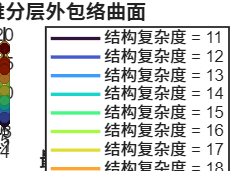

clc;clear;


i = 13;
msg = sprintf('F:\\Archive 归档\\0522_mp\\data\\result_run_%d.mat',i);
load(msg);
P_final = result.fval;

for j = 1:21
    if j == i
        disp('self j');
        j
    else
        msg = sprintf('F:\\Archive 归档\\0522_mp\\data\\result_run_%d.mat',j);
        load(msg);
        P_final = merge_pareto_incremental(P_final, result.fval)    
    end
end

% plot_pareto_smooth(P_final);


plot_fitted_surface(P_final)

